## APPENDIX B

### General Code

### Inputs

%Motor & Panel System
k_t = 0.53;
k_b = 0.5617;
GearRatio = 0.6;%N1/N2
Beta = deg2rad(0); %deg from 0 to 90
I_System = 0.4;
I_motor = 0.00046;
I_Pole = 0.6317;
I_Gear = 1.62e-3;
D_System = 43.25;
D_Motor = 0.1 + 22.71;
L_Motor = 0.05;
R_Motor = 25.3;
Mu_s_Thrust = 0.0015;
Mu_s_Roller = 0.0012;
Pole_Diam = 0.15;
SystemMass = 200*9.81;
Mass_Panel = 78.2;
Length_Panel = 2.384;
Width_Panel = 2.606;
Thickness_Panel = 0.035;

MOI_Linear = (Mass_Panel/12)*(Length_Panel^2 - Length_Panel^2*Beta^2 + (Thickness_Panel*Beta)^2 + Width_Panel^2) + I_Pole + I_Gear;
I_eq_Linear = I_motor + GearRatio^2*MOI_Linear;
D_eq_Linear = D_Motor + GearRatio^2*D_System;

I_eq_NonLinear = I_motor + GearRatio^2*((Mass_Panel/12)*(Length_Panel^2*cos(Beta)^2 + Thickness_Panel^2*sin(Beta)^2 + Width_Panel^2)+I_Pole+I_Gear);

TF_Num = GearRatio*[k_t];
TF_Denom = [I_eq_Linear*L_Motor, (D_eq_Linear*L_Motor + I_eq_Linear*R_Motor), (D_eq_Linear*R_Motor + k_t*k_b),0];

TF_Num_2 = GearRatio.*[k_t*I_eq_Linear D_eq_Linear*k_t];
TF_Denom_2 = [I_eq_Linear*L_Motor (I_eq_Linear*R_Motor + D_eq_Linear*L_Motor) (D_eq_Linear*R_Motor + k_t*k_b)];

TF_Num_3 = GearRatio.*1;
TF_Denom_3 = [I_eq_Linear D_eq_Linear 0];

LTI_Total = tf(TF_Num,TF_Denom);
LTI_Motor = tf(TF_Num_2,TF_Denom_2);
LTI_Plant = tf(TF_Num_3,TF_Denom_3);

### Time Responses - Time Domain

See formatting plot code

### Time Responses - Frequency Domain

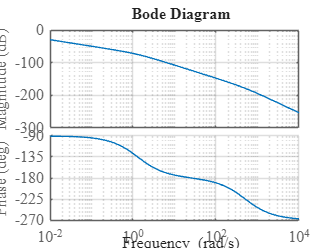

bode(LTI_Total)
hold on
grid on
set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')
box off
hold off

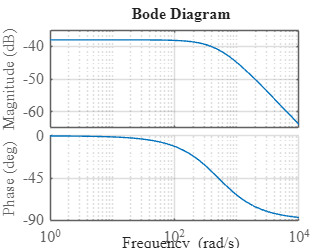


bode(LTI_Motor)
hold on
grid on
set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')
box off
hold off

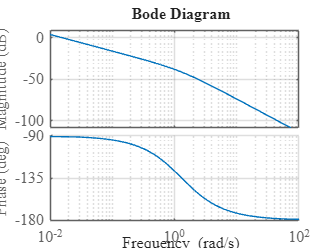


bode(LTI_Plant)
hold on
grid on
set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')
box off
hold off

### Stability Analysis - Routh Hurwitz Verification

roots(TF_Denom)

ans =          0
 -505.9996
   -1.3017


roots(TF_Denom_2)

ans =  -505.9996
   -1.3017


roots(TF_Denom_3)

ans =          0
   -1.3013


### Stability Analysis - Nyquist Stability Plot

figure
N1 = nyquistplot(LTI_Total)


N1 =

	resppack.nyquistplot



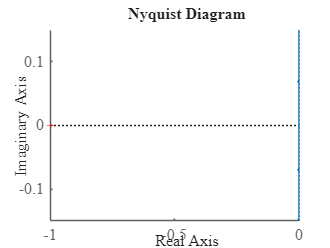

set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')
box off
grid off


figure
N2 = nyquistplot(LTI_Motor)


N2 =

	resppack.nyquistplot



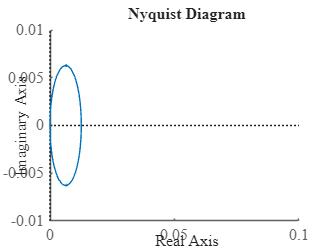

set(gcf,'color','w');
axis([0,0.1,-1e-2,1e-2])
fontname("Times New Roman")
fontsize(12,'points')
box off
grid off

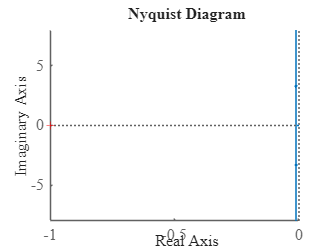


nyquistplot(LTI_Plant)
set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')
box off
grid off

### Root Locus Stability

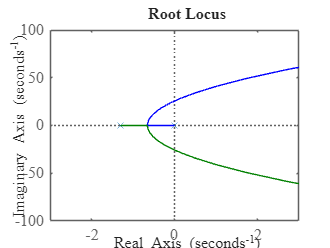

rlocus(LTI_Total)
axis([-3,3,-100,100])
set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')

### Running the Simulation

load sunSummer.mat
sunTime = sunTime*60*60;
sunTime = sunTime - sunTime(1);
sunPos = sunPosition';
sunElevation = sunElevation';
sunTime = sunTime';
StartingPosition = sunPos(1);

### Analytical Solution

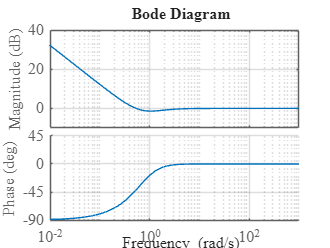

K = 908;
Num = [1 + K*0.318];
Denom = [1 501.424 712];
s = tf('s');
h=(1+(K*0.318)/(s*(s + 1.424)*(s + 500))); %Transfer function

bode(h), grid
set(gcf,'color','w');
fontname("Times New Roman")
fontsize(12,'points')
box off